## ROUTE MAPPING

% Get coordinates of Mawson Station
Mawson_coords = scarloc('mawson station');
Spatial_res = 1;
% Create the map figure
figure('Position', [100, 100, 1200, 800]);
% Plot the map with Mawson Station and bedmachine data
mapzoomps(Mawson_coords(1)-0.4, Mawson_coords(2), 'size', [100 100], 'frame', 'off');
hold on;
scatterps(Mawson_coords(1), Mawson_coords(2), 10,'Marker', 'd', 'MarkerFaceColor', 'r');
scarlabel('Mawson');
title('Step 1: Select the waypoints along the route');
box on;
% Customize the plot as needed
scalebarps;
% Plot bedmachine data
[bed,lat,lon] = bedmachine_data('bed',xlim,ylim,'geo');
pcolorps(lat, lon, bed);
cmocean('grey')       % optional colormap
bedmachine('surface','contour',0:100:5000);
cb = colorbar;
ylabel(cb,'elevation wrt geoid (m)');
bedmachine('coast','y');
mapzoomps('nw','frame','off');
view([-90, 90]);
hold off;
disp('Select waypoints on the map. Press enter when done :)');

Select waypoints on the map. Press enter when done :)


[lat,lon] = coord;

% Create the figure for the PNG picture of the routes
figure;
image = imread('Framnes_mapping.tif'); % Specify the path to your PNG picture
imshow(image);
title('Routes framnes mountains-mawson');

% Create another figure for the legend
figure;
legend = imread('Legend.png');
imshow(legend);

% Keep the figure open until closed by the user
% Assign start and end points
startlat = lat(1);
startlon = lon(1);
endlat = lat(end);
endlon = lon(end);
intermediatewaypoints = [lat(2:end-1) lon(2:end-1)];
waypoints = [startlat startlon; intermediatewaypoints; endlat endlon];
[lati,loni] = pspath([startlat endlat],[startlon endlon],Spatial_res);  %gives interpolated points between the specified waypoints
linpath = [lati ; loni]';       
path = [startlat,startlon];

% Initialize cell arrays to store latitude and longitude
path_lat = startlat;
path_lon = startlon;

for k = 1:height(waypoints)
    if k < height(waypoints)
        [interlat, interlon] = pspath([waypoints(k,1) waypoints(k+1,1)], [waypoints(k,2) waypoints(k+1,2)], Spatial_res);
        
        % Append new latitude and longitude values
        path_lat = [path_lat; interlat'];
        path_lon = [path_lon; interlon'];
    end
end

% Concatenate latitude and longitud
% e arrays
path = [path_lat, path_lon];

d = pathdistps(path(:,1)', path(:,2)', 'km')';
z = bedmachine_interp('surface', path(:,1)', path(:,2)')';
%figure;
% Subplot 2: Plot of Distance traveled vs Surface elevation
%plot(d, z)
%xlabel 'Distance traveled (km)'
%ylabel 'Surface elevation (m)'
%grid on

% Convert distance to meters
d_meters = d*1000;  % Convert kilometers to meters

%envdata=ncdataset('env_data.grib')

% Subplot 3: Plot of Slope vs Distance traveled
%subplot(2, 2, 2);

% Calculate slope (gradient) using finite differences
dz = diff(z);  % Calculate difference in elevation
dd = diff(d_meters);  % Calculate difference in distance (in meters)
slope = dz ./ dd;  % Calculate slope

% Plot the slope
%plot(d_meters(2:end), slope)
%xlabel 'Distance traveled (meters)'
%ylabel 'Slope (%)'
%grid on

## SLICER FUNCTION AND VELOCITY PROFILER

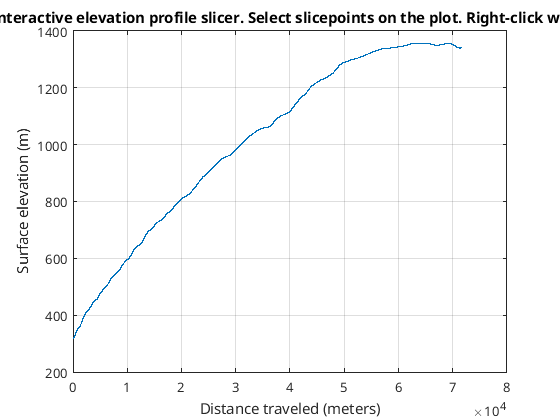

% Subplot 4: Interactive Elevation Profile Slicer
figure
plot(d_meters, z)
xlabel 'Distance traveled (meters)'
ylabel 'Surface elevation (m)'
grid on

title('Step 2: Interactive elevation profile slicer. Select slicepoints on the plot. Right-click when done :)');
[slicepoints_x, ~] = ginput();

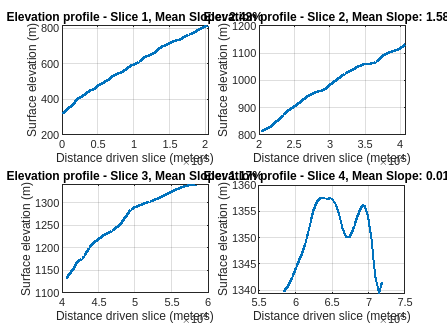

endslice_x = d_meters(end);
endslice_y = z(end);

num_slices = length(slicepoints_x) + 1;

% Calculate the number of rows and columns for the subplot grid
cols = ceil(sqrt(num_slices));
rows = ceil(num_slices / cols);

% Create a figure with a subplot grid
figure

% Cell array to store slice-specific data
slice_data = cell(num_slices, 2);
mean_slopes = zeros(num_slices, 1);  % Store slopes in a column vector
for i = 1:num_slices
    if i == 1
        % for the first slice, start from the real distance
        start_distance = 0;
    else
        % for subsequent slices, start from the end of the previous slice
        start_distance = slice_data{i-1, 1}(end);
    end
    
    % handle the last slice differently
    if i == num_slices
        end_distance = endslice_x;
    else
        end_distance = slicepoints_x(i);
    end
    
    % find indices corresponding to the selected slice
    [~, start_index] = min(abs(d_meters - start_distance));
    [~, end_index] = min(abs(d_meters - end_distance));

    % Extract the elevation and distance data for the slice
    slice_data{i, 1} = d_meters(start_index:end_index);
    slice_data{i, 2} = z(start_index:end_index);

    % adjust distance to start from the real distance
    slice_data{i, 1} = slice_data{i, 1} - slice_data{i, 1}(1) + start_distance;

    % calculate the mean slope for the slice in percentage
    elevation_change = slice_data{i, 2}(end) - slice_data{i, 2}(1);
    distance_driven = slice_data{i, 1}(end) - slice_data{i, 1}(1);
    mean_slope = (elevation_change / distance_driven) * 100;
    mean_slopes(i) = mean_slope;  % Store mean slope in the column vector
    
    % calculate the subplot index based on the current iteration
    subplot(rows, cols, i);
    plot(slice_data{i, 1}, slice_data{i, 2}, 'LineWidth', 2);
    xlabel 'Distance driven slice (meters)'
    ylabel 'Surface elevation (m)'
    title(['Elevation profile - Slice ', num2str(i), ', Mean Slope: ', num2str(mean_slope, '%.2f'), '%']);
    grid on
end


slice_velocities = zeros(1, num_slices);
for i = 1:num_slices
    % prompt the user to enter the velocity profiles per slice
    prompt = ['Enter velocity for Slice ', num2str(i), ' (in km/h): '];
    slice_velocities(i) = input(prompt);
end


## timesim calcs

clear slice_times
slice_times = zeros(1, num_slices);
% ugly ass coding sorry
total_travel_time = 0;
for i = 1:num_slices
    distance_driven = slice_data{i, 1}(end) - slice_data{i, 1}(1);
    travel_time = distance_driven / slice_velocities(i);
    slice_times(i) = travel_time;
    total_travel_time = total_travel_time + travel_time;
end
time_vector = (1:1:total_travel_time)';
vel_times = ones(length(time_vector), 1);
slope_times = ones(length(time_vector), 1);

current_time = 0;
for i = 1:num_slices
    slice_duration = ceil(slice_times(i));
    slice_vel = slice_velocities(i);
    slice_slope = mean_slopes(i)
    for j = 1:slice_duration
        vel_times(current_time + j) = slice_vel;
        slope_times(current_time + j) = slice_slope;
    end
    
    % Update the current time
    current_time = current_time + slice_duration;
    vel_times = vel_times(3:1:length(vel_times));
    slope_times = slope_times(3:1:length(slope_times));
end

slice_slope = 2.4308

slice_slope = 1.5753

slice_slope = 1.1670

slice_slope = 0.0146

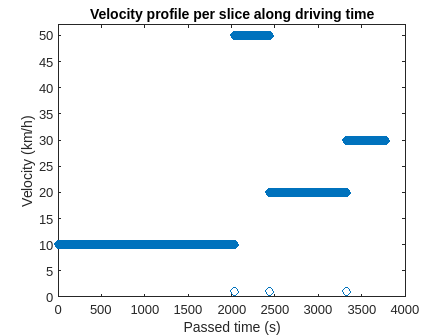

velocity_profile = [time_vector, vel_times];
slope_profile = [time_vector, slope_times];
figure;
plot(time_vector,vel_times,'o')
ylim([0 max(slice_velocities)+2]);
ylabel('Velocity (km/h)');
xlabel('Passed time (s)');
title('Velocity profile per slice along driving time')

## Simulation parameters

T_start = 0.0;           % Simulation start time
T_stop = time_vector(end);  % Simulation end time (assuming time_vector is defined)
T_step = 1;               % Simulation timestep in seconds
Crr = 0.15;                % Rolling friction coefficient

Mass_values = [100 200 300 400 500 600 700 800];        % Vehicle total mass
Battmassfrac_values = 0.1:0.05:0.5;       % Fraction of the total mass allocated to the battery

g = 9.81;                 % Gravitational acceleration
BatteryEdensity1 = 150;   % Battery energy density in Wh/kg of battery candidate number 1
BatteryEdensity2 = 200;   % Battery energy density in Wh/kg of battery candidate number 2
BatteryEdensity3 = 400;   % Battery energy density in Wh/kg of battery candidate number 3
BatteryEdensIcecube = 134.4;  % Battery energy density in Wh/kg of battery candidate number 3
Packingfactor = 2;        % Offset to the energy density

kwh_used_values = zeros(numel(Mass_values)); % Preallocate matrix for efficiency

for mass_idx = 1:numel(Mass_values)
    Mass = Mass_values(mass_idx);
    
    for batt_frac_idx = 1:numel(Battmassfrac_values)
        Battmassfrac = Battmassfrac_values(batt_frac_idx);
        
        % Run the simulation with current mass and battery mass fraction
        simOut = sim("Mass_est.slx", 'ExternalInput', num2str(Mass), 'ExternalInput', num2str(Battmassfrac));    
        
        % Store the simulation result
        kwh_used_values(mass_idx) = simOut.simout(end);
        e_dep(batt_frac_idx) = simOut.simout1(end);
        energy_left_in_battery = batt_frac_idx*Batte_dep(batt_frac_idx)
        disp(['Simulation completed for mass = ', num2str(Mass), ', Battmassfrac = ', num2str(Battmassfrac)]);
    end
end

Simulation completed for mass = 100, Battmassfrac = 0.1
Simulation completed for mass = 100, Battmassfrac = 0.15
Simulation completed for mass = 100, Battmassfrac = 0.2
Simulation completed for mass = 100, Battmassfrac = 0.25
Simulation completed for mass = 100, Battmassfrac = 0.3
Simulation completed for mass = 100, Battmassfrac = 0.35
Simulation completed for mass = 100, Battmassfrac = 0.4
Simulation completed for mass = 100, Battmassfrac = 0.45
Simulation completed for mass = 100, Battmassfrac = 0.5
Simulation completed for mass = 200, Battmassfrac = 0.1
Simulation completed for mass = 200, Battmassfrac = 0.15
Simulation completed for mass = 200, Battmassfrac = 0.2
Simulation completed for mass = 200, Battmassfrac = 0.25
Simulation completed for mass = 200, Battmassfrac = 0.3
Simulation completed for mass = 200, Battmassfrac = 0.35
Simulation completed for mass = 200, Battmassfrac = 0.4
Simulation completed for mass = 200, Battmassfrac = 0.45
Simulation completed for mass = 200, Bat

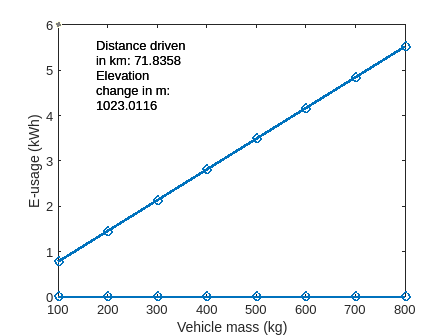

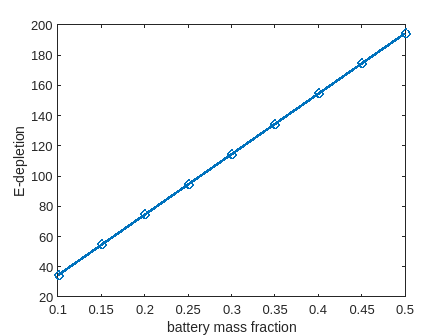

% Calculate total change in elevation
total_change_elevation = z(end) - z(1);

figure;

plot(Mass_values, kwh_used_values, 'o-', 'LineWidth', 2);
xlabel('Vehicle mass (kg)');
ylabel('E-usage (kWh)');
legend('Dist. driven = ', num2str(distance_driven));
total_change_elevation = z(end) - z(1); 

textbox_str = {['Distance driven in km: ', num2str(end_distance/1000)];...
               ['Elevation change in m: ', num2str(total_change_elevation)]};
annotation('textbox', [0.2, 0.7, 0.25, 0.2], 'String', textbox_str, 'EdgeColor', 'none');
annotation('textbox', [0.2, 0.7, 0.25, 0.2], 'String', textbox_str, 'EdgeColor', 'none');